# Guided Filter在图像的平滑处理应用

## 1.读入p图像和I图像

input_p = imread("./input_image.png");
guide_I = imread("./input_image.png");
% 原图和引导图相同,做平滑处理

## 2.展示原图

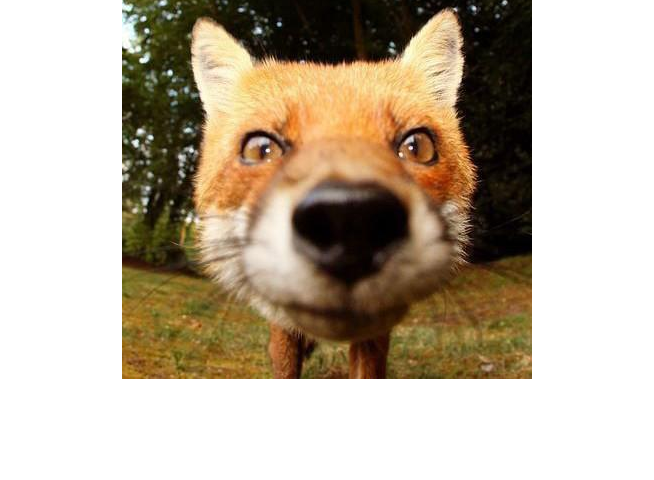

figure("NumberTitle","off","Name","原图");
imshow(input_p);

## 3.高斯滤波

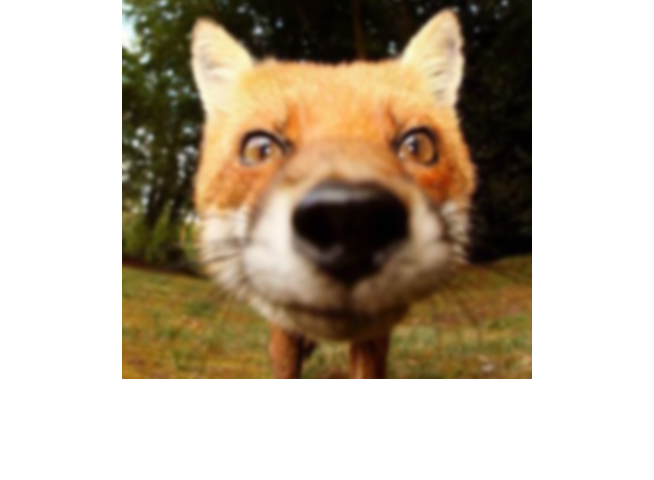

figure("NumberTitle","off","Name","高斯滤波")
output_gauss = imgaussfilt(input_p,2);
imshow(uint8(output_gauss));

## 4.Guided Filter

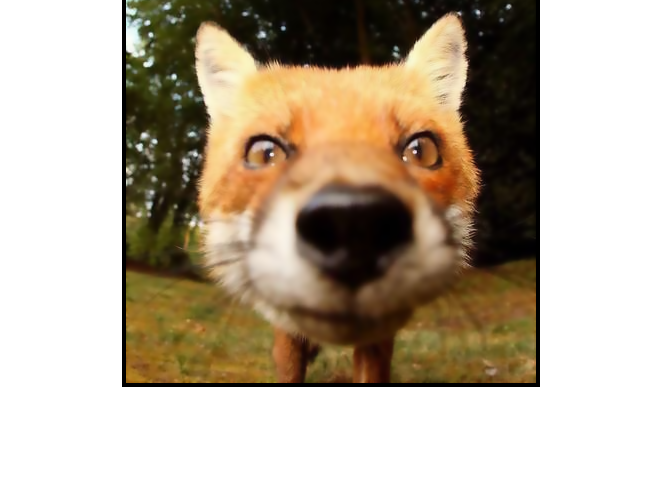

output_q = guided_filter(input_p,guide_I, 5);
figure("NumberTitle","off","Name","引导滤波");
imshow(uint8(output_q));

## 附1:Guided Filter构建

function [output_q] = guided_filter(input_p,guide_I,k)
channel_num = 3;
input_p_padding = padarray(input_p,[k-1,k-1],0);
guide_I_padding = padarray(guide_I,[k-1,k-1],0);
input_p_padding = double(input_p_padding)/255;
guide_I_padding = double(guide_I_padding)/255;
ak_matrix = zeros(size(input_p_padding));
bk_matrix = zeros(size(input_p_padding));
image_width = size(input_p_padding,1);
image_height = size(input_p_padding,2);
for channel = 1:1:channel_num
    for i = k:1:(image_width-k+1)
        for j = k:1:(image_height-k+1)
            [ak,bk] = get_ak_bk(i,j,channel,input_p_padding,guide_I_padding,k);
            ak_matrix(i,j,channel) = ak;
            bk_matrix(i,j,channel) = bk;
        end
    end
end
guide_I_padding = double(guide_I_padding);
output_q = zeros(size(guide_I_padding));
output_q = ak_matrix .* guide_I_padding + bk_matrix;
output_q = output_q .* 255;
end

## 附2:通过滑动窗口求取a_k,b_k

function [ak,bk] = get_ak_bk(i,j,channel,input_p_padding,guide_I_padding,k)
ak = 0;
bk = 0;
ak_sum = 0;
bk_sum = 0;
epsilon = 0.007;
omega = k .^ 2;
window_start_x = i-k+1;
window_start_y = j-k+1;
for m = 1:1:k
    for n = 1:1:k
        pk_window = input_p_padding(window_start_x:window_start_x+k-1,window_start_y:window_start_y+k-1,channel);
        Ik_window = guide_I_padding(window_start_x:window_start_x+k-1,window_start_y:window_start_y+k-1,channel);
        pk_Ik_mean = sum(sum(pk_window .* Ik_window))/omega;
        pk_mean = sum(pk_window(:))/omega;
        Ik_mean = sum(Ik_window(:))/omega;
        Ik_squres_mean = sum(sum(pk_window .* pk_window))/omega;
        ak = (pk_Ik_mean - pk_mean*Ik_mean)/(Ik_squres_mean - Ik_mean .^ 2 + epsilon);
        bk = pk_mean - ak * Ik_mean;
        ak_sum = ak_sum + ak;
        bk_sum = bk_sum + bk;
        window_start_x = window_start_x + 1;
    end
    window_start_x = i - k+1;
    window_start_y = window_start_y + 1;
end
ak = ak_sum/omega;
bk = bk_sum/omega;
end